# Hai Nguyen 16 April 2021

clear all; clc; close all;
rand('state',20);
randn('state',18);

## Initialize fake data

Mesh

n = 1000; sp = floor(n/10);
s = linspace(0,1,n+1)'; t = s;

% Discretize the deblurring kernel
beta = 0.05;
a = 1/sqrt(2*pi*beta^2)*exp(-0.5*(1/beta^2)*t.^2);
A = 1/n*toeplitz(a);

% Truth
xtrue = 10*(t-0.5).*exp(-0.5*1e2*(t-0.5).^2) -0.8 + 1.6*t;

% ------------additive noise-----------
noise = 5;       % Noise level in percentages of the max. of noiseless signal
y0 = A*xtrue;    % Noiseless signal
STD_noise = max(abs(y0))*noise/100;                % STD of the additive noise
y_obs = y0 + STD_noise*randn(n+1,1);

d = size(y_obs,1); p = size(xtrue,1);
% Data covariance
sigma_square = STD_noise^2;
SIGMA_SqR =  STD_noise * eye(d);
SIGMA_SqR_INV = 1/STD_noise * eye(d);

## Computations for different cases

alpha_square = 1;  % regularization parameters 

% x prior
gamma = sqrt(sigma_square/alpha_square);
GAMMA_SqR = gamma * eye(p);
GAMMA_SqR_INV = 1/gamma * eye(p);

% change of varibale ::: whitening x = \GAMMA_SqR * x_bar 
A_bar = SIGMA_SqR_INV * A * GAMMA_SqR;
y_obs_bar = SIGMA_SqR_INV * y_obs;


## Active subspace matrices

C = A_bar' * (A_bar*A_bar' + y_obs_bar*y_obs_bar') * A_bar;
[W,S_ddT,W] = svd(C);

C_ACT_M = A_bar' * (A_bar * A_bar') * A_bar;
[V,S_free,V] = svd(C_ACT_M);

## PLot results

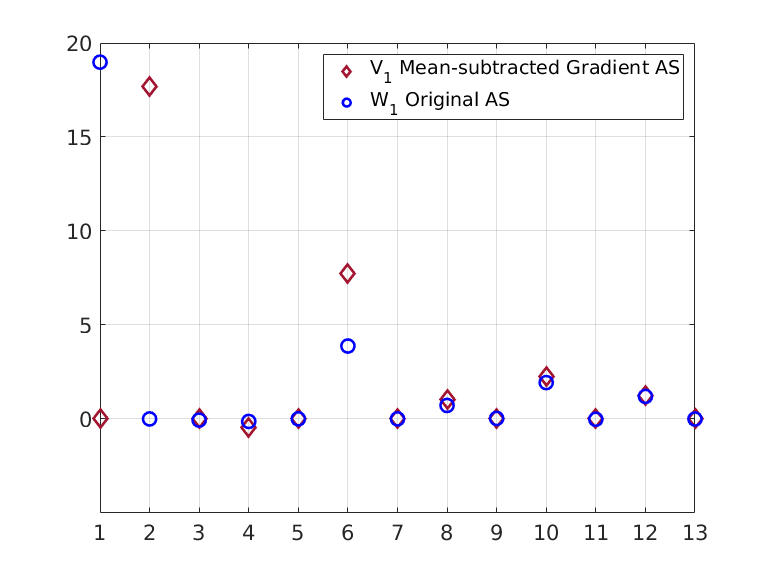

VT_d = V'*xtrue;
WT_d = W'*xtrue;

r = 13;

figure('Units','normalized','Position',[0 0 0.15 0.4], 'PaperPositionMode', 'auto'); hold on
        set(gca,'FontSize', 16, 'fontname', 'Times New Roman' )
hold on
scatter(1:r,VT_d(1:r),100,'Marker','d','MarkerEdgeColor',[0.6350 0.0780 0.1840],'Linewidth',2,'DisplayName','V_1 Mean-subtracted Gradient AS')

scatter(1:r,WT_d(1:r),100,'Marker','o','MarkerEdgeColor','b','Linewidth',2,'DisplayName','W_1 Original AS')
xlim([1 r])

% xlabel('Active subspace direction indices')
% ylabel('Coefficients   d_i = (d,\cdot)')
legend

xticks([1:r])
yticks([0, 5, 10, 15, 20])
grid on 
box on
saveas(gcf,['1D_Decon_r_Projection'],'epsc')

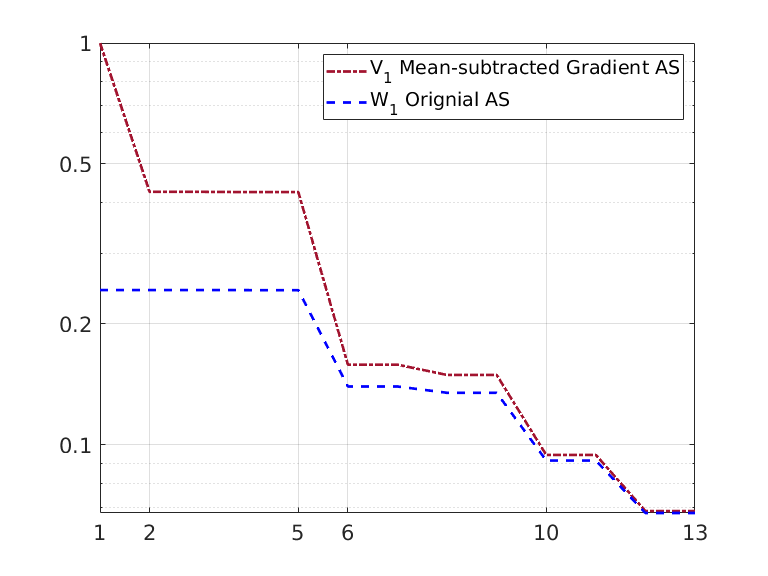

for i = 1:r
    d_i = V(:,1:i) * VT_d(1:i);
    Energy_V(i) = norm(xtrue - d_i) / norm(xtrue);
    
    d_i = W(:,1:i) * WT_d(1:i);
    Energy_W(i) = norm(xtrue - d_i) / norm(xtrue);
end
figure('Units','normalized','Position',[0 0 0.15 0.4], 'PaperPositionMode', 'auto'); hold on
set(gca,'FontSize', 16, 'fontname', 'Times New Roman' )
set(gca, 'YScale', 'log')
hold on
loglog(Energy_V,'Color',[0.6350 0.0780 0.1840],'Linestyle','-.','Linewidth',2,'DisplayName','V_1 Mean-subtracted Gradient AS');
loglog(Energy_W,'Color','b','Linestyle','--','Linewidth',2,'DisplayName','W_1 Orignial AS');
% xlabel('Rank of active subspace')
% ylabel('||d - d_{r} ||_2 / ||d||_2')
xticks([1 2 5 6 10 r])
yticks([0.0 .1 .2 .5 1])
axis([1 r 0 1])
legend('Location','northeast')
box on
grid on
saveas(gcf,['1D_Decon_error_Projection'],'epsc')